# PART B: ADAPTIVE EQUALIZATION

## setup

N = 1000;
V = [-1, 1];
train = V(randi([1,2], 1, N));
window = 50;

## helper functions

function [gn, en, yn, xn, noi_power] = run_equalizer(train, h, mu, M, delay_idx, snr_db, N)
    % channel convolution
    chan_output = conv(h, train);
    chan_output = chan_output(1:N);

    % adding noise
    sig_power = mean(chan_output.^2);
    noi_power = sig_power / 10^(snr_db/10);
    xn        = chan_output + sqrt(noi_power) .* randn(1, N);

    delayed_train = [zeros(1, delay_idx), train(1:end-delay_idx)];

    
    gn = zeros(1, M+1);        
    yn = zeros(1, N);
    en = zeros(1, N);

    for i = M+1:N
        x_inp = xn(i:-1:i-M);
        yn(i) = dot(gn, x_inp);
        en(i) = delayed_train(i) - yn(i);
        gn    = gn + 2*mu * en(i) * x_inp;
    end
end

function plot_channel(h, snr_db, mu, M)
    figure('Position', [100, 100, 600, 700]);   % [x, y, width, height]
    sgtitle({compose("Channel Plots: h=%s", mat2str(h)), ...
         compose("M=%d, μ=%.5f, SNR=%.1fdB", M, mu, snr_db)});
    subplot(3,1,1);
    stem(h);
    xlabel('n'); ylabel('h[n]');
    title('Channel Impulse Response');
    grid on;

    subplot(3,1,2);
    [H_chan, w] = freqz(h, 1, 1024);
    plot(w/pi, 20*log10(abs(H_chan)));
    xlabel('\omega/\pi'); ylabel('|H| (dB)');
    title('Channel Frequency Response');
    grid on;

    subplot(3,1,3);
    zplane(h, 1);
    title('Channel Pole-Zero Plot');
end

function plot_equalizer(h, gn_conv, en, snr_db, mu, M, window)
    figure('Position', [100, 100, 600, 700]);
    sgtitle({"Equalizer Plots: h=" + mat2str(h), ...
             compose("M=%d, μ=%.5f, SNR=%.1fdB", M, mu, snr_db)});

    subplot(3,1,1);
    stem(gn_conv);
    xlabel('n'); ylabel('g[n]');
    title(sprintf('Equalizer Impulse Response, Converged (M=%d)', M));
    grid on;

    [G_conv, w] = freqz(gn_conv, 1, 1024);
    subplot(3,1,2);
    plot(w/pi, 20*log10(abs(G_conv)));
    xlabel('\omega/\pi'); ylabel('|G| (dB)');
    title('Equalizer Frequency Response, Converged (dB)');
    grid on;

    subplot(3,1,3);
    mse = movmean(en(M+1:end).^2, window);
    plot(10*log10(mse));
    xlabel('Iteration n'); ylabel('MSE (dB)');
    title(sprintf('Learning Curve (M=%d, \\mu=%.4f, SNR=%ddB)', M, mu, snr_db));
    grid on;
end

function plot_cascade(h, gn_conv, snr_db, mu, M)
    figure('Position', [100, 100, 600, 600]);
    sgtitle({"Cascade (h*g) Plots: h=" + mat2str(h), ...
             compose("M=%d, μ=%.5f, SNR=%.1fdB", M, mu, snr_db)});
    cascade_h = conv(h, gn_conv);
    [H_cas, w] = freqz(cascade_h, 1, 1024);

    subplot(2,1,1);
    stem(cascade_h);
    xlabel('n'); ylabel('Amplitude');
    title('Cascade (h * g) Impulse Response (converged)');
    grid on;

    subplot(2,1,2);
    plot(w/pi, 20*log10(abs(H_cas)));
    hold on;
    yline(0, 'r--', 'LineWidth', 1.0);
    hold off;
    ylim([-inf 5]);
    xlabel('\omega/\pi'); ylabel('Magnitude (dB)');
    title('Cascade Frequency Response, Converged (dB)');
    grid on;
end

function [ber_uneq, ber_eq] = compute_bit_error(h, gn_c, M, delay_idx, noi_power, V)
    N_test  = 5000;
    s_test  = V(randi([1,2], 1, N_test));
    x_test  = conv(s_test, h);
    x_test  = x_test(1:N_test);
    x_test  = x_test + sqrt(noi_power)*randn(1, N_test);

    s_test_del = [zeros(1,delay_idx), s_test(1:N_test-delay_idx)];

    % unequalized
    dec_uneq = sign([zeros(1,delay_idx), x_test(1:N_test-delay_idx)]);
    ber_uneq = sum(dec_uneq ~= s_test_del) / N_test;

    % equalized
    y_test = zeros(1, N_test);
    for k = M+1:N_test
        x_vec     = x_test(k:-1:k-M);
        y_test(k) = dot(gn_c, x_vec);
    end
    dec_eq  = sign(y_test(M+1:end));
    ber_eq  = sum(dec_eq ~= s_test_del(M+1:end)) / (N_test-M);
end

## TESTS

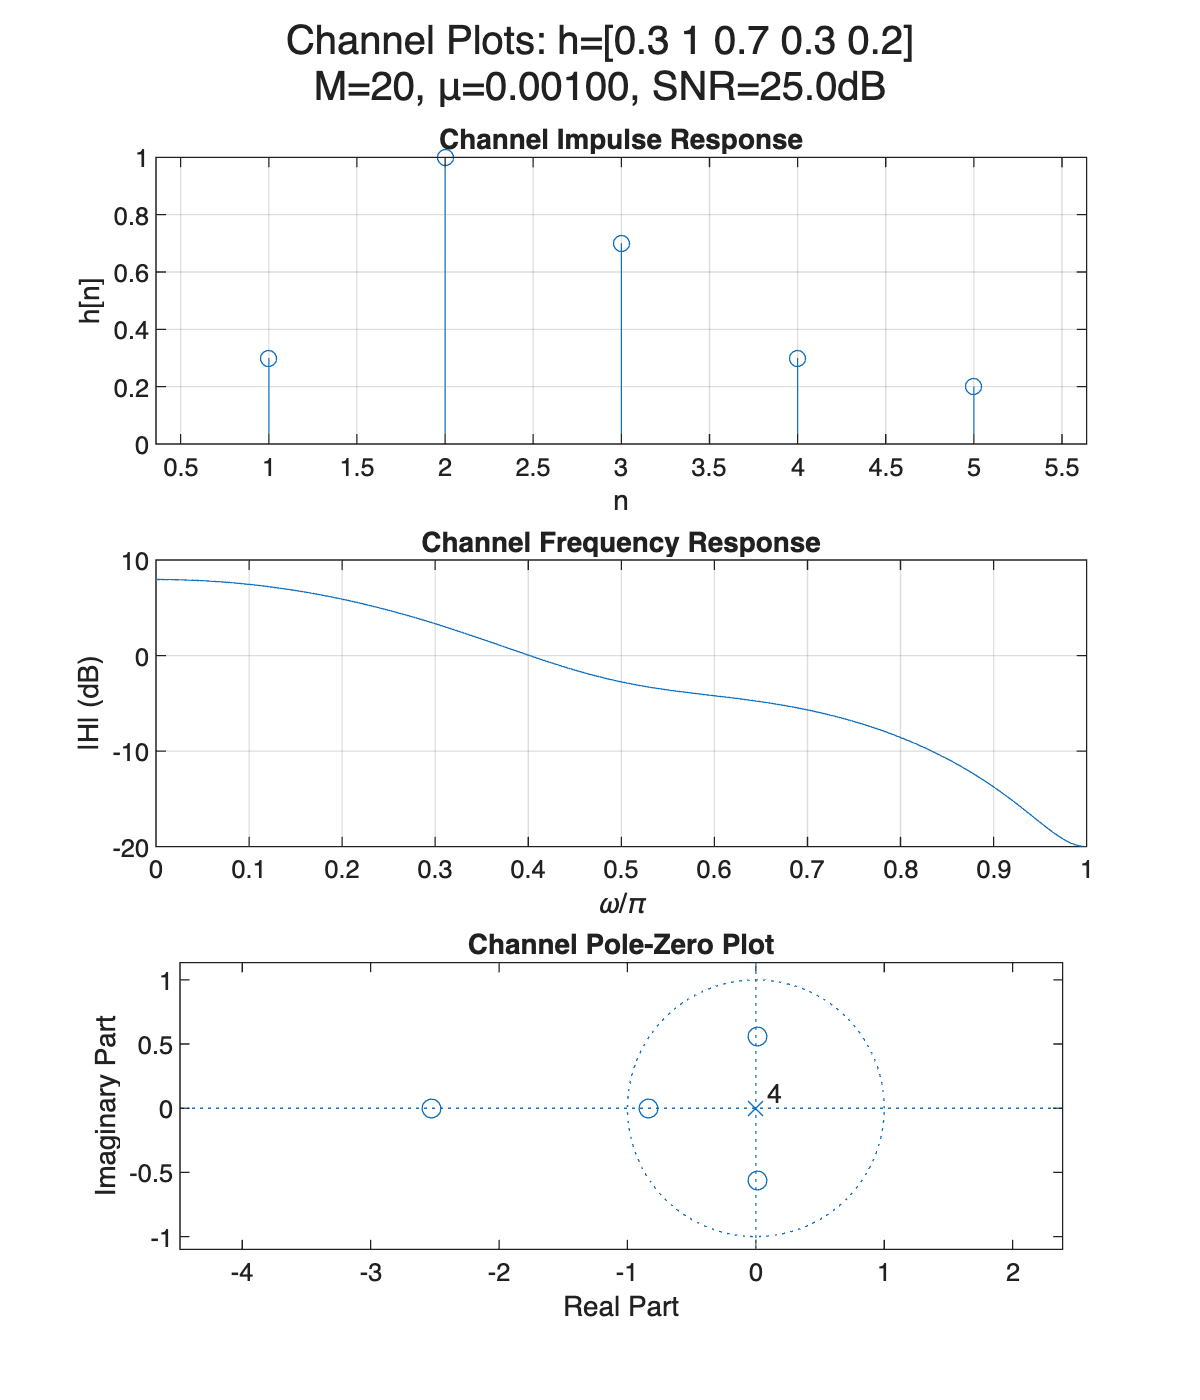

% TEST 1 (basic config)
snr_db = 25;
h = [0.3, 1, 0.7, 0.3, 0.2];
mu = 0.001;
M = 20;
delay_idx = 2;

figure; plot_channel(h, snr_db, mu, M);

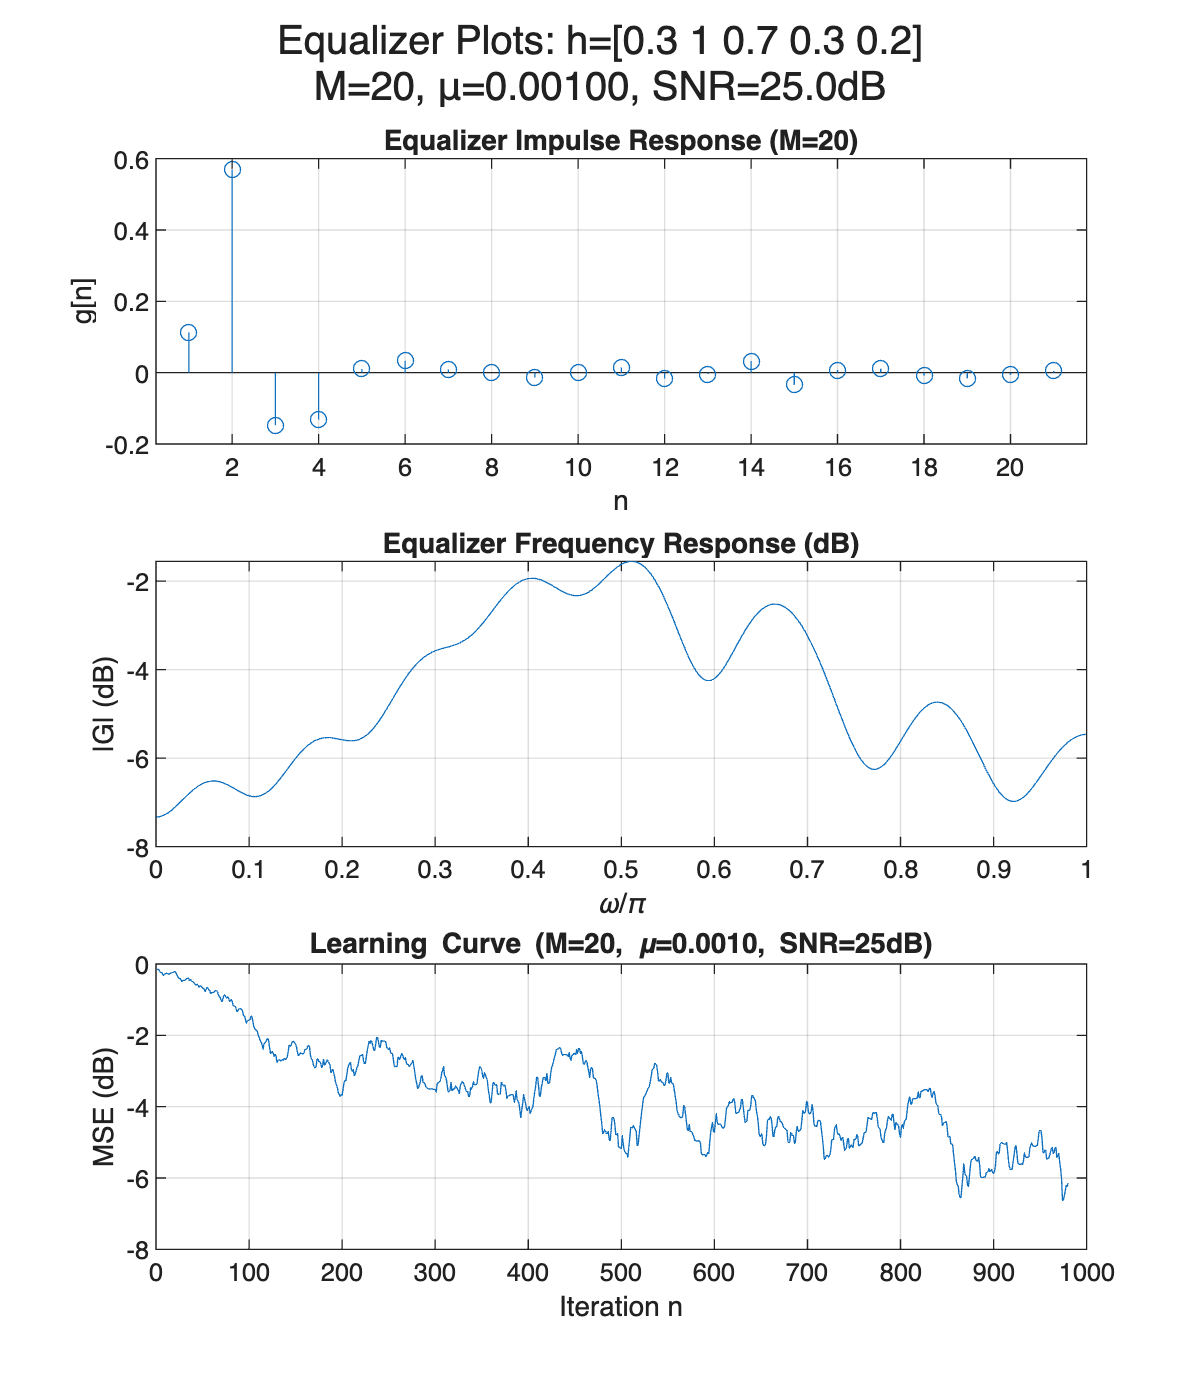


train_c = V(randi([1,2], 1, 5000));
[gn_c, en_c, ~, ~, noi_power_c] = run_equalizer(train_c, h, mu, M, delay_idx, snr_db, 5000);

figure; plot_equalizer(h, gn_c, en_c, snr_db, mu, M, window);

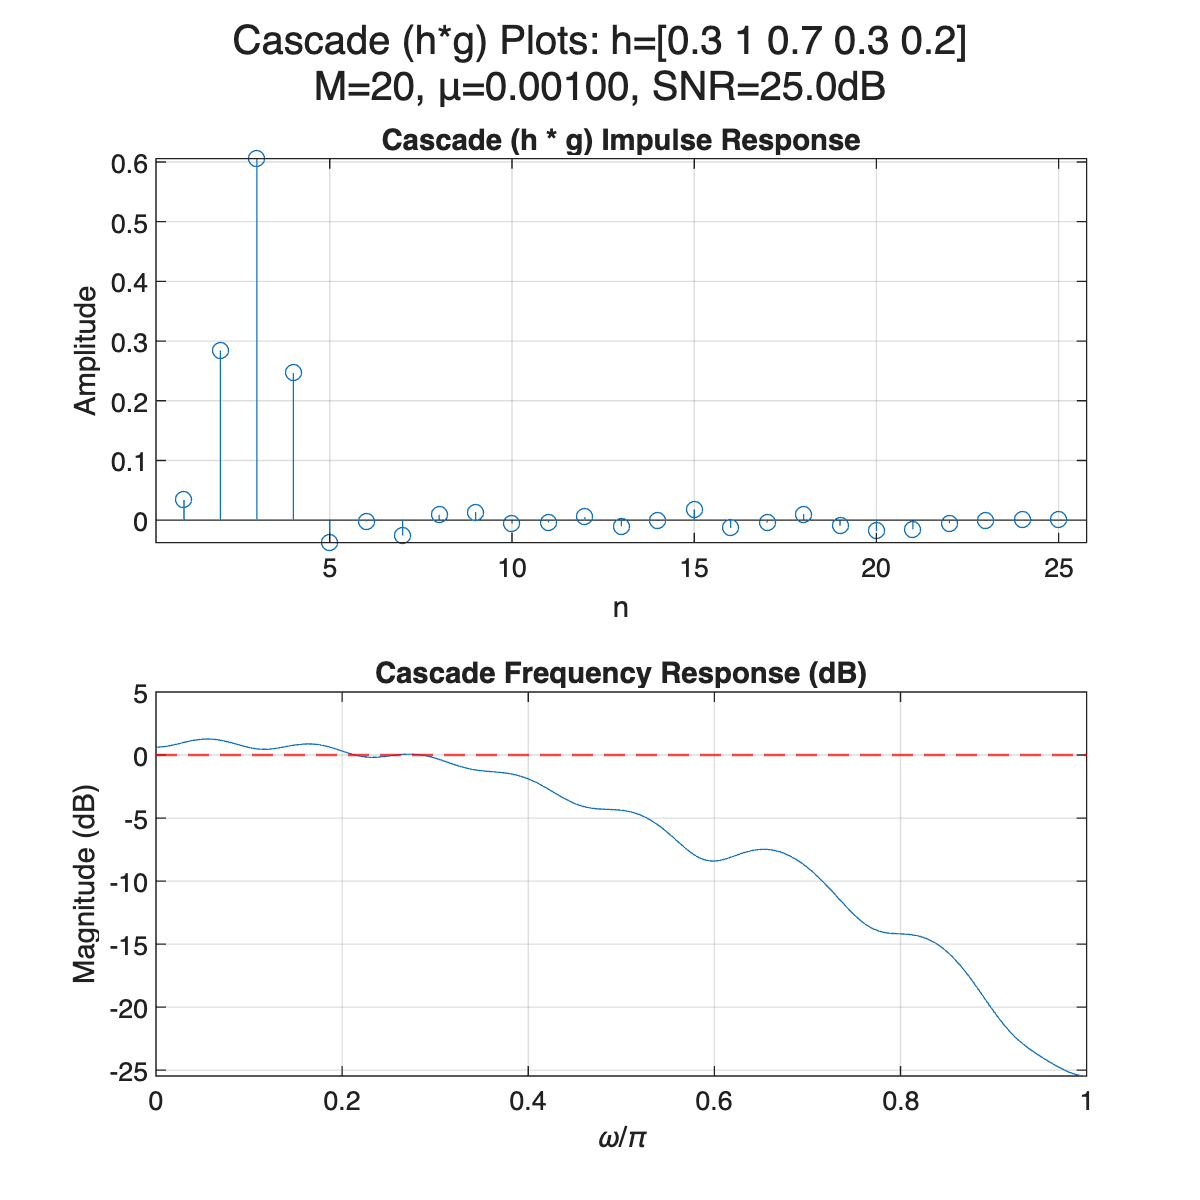

figure; plot_cascade(h, gn_c, snr_db, mu, M);


[BER_uneq, BER_eq] = compute_bit_error(h, gn, M, delay_idx, noi_power, V);
fprintf('Test 1 (SNR=%ddB, M=%d, mu=%.4f)\n', snr_db, M, mu);

Test 1 (SNR=25dB, M=20, mu=0.0010)


fprintf('Unequalized BER: %.4f\n', BER_uneq);

Unequalized BER: 0.3798


fprintf('Equalized   BER: %.4f\n', BER_eq);

Equalized   BER: 0.0420


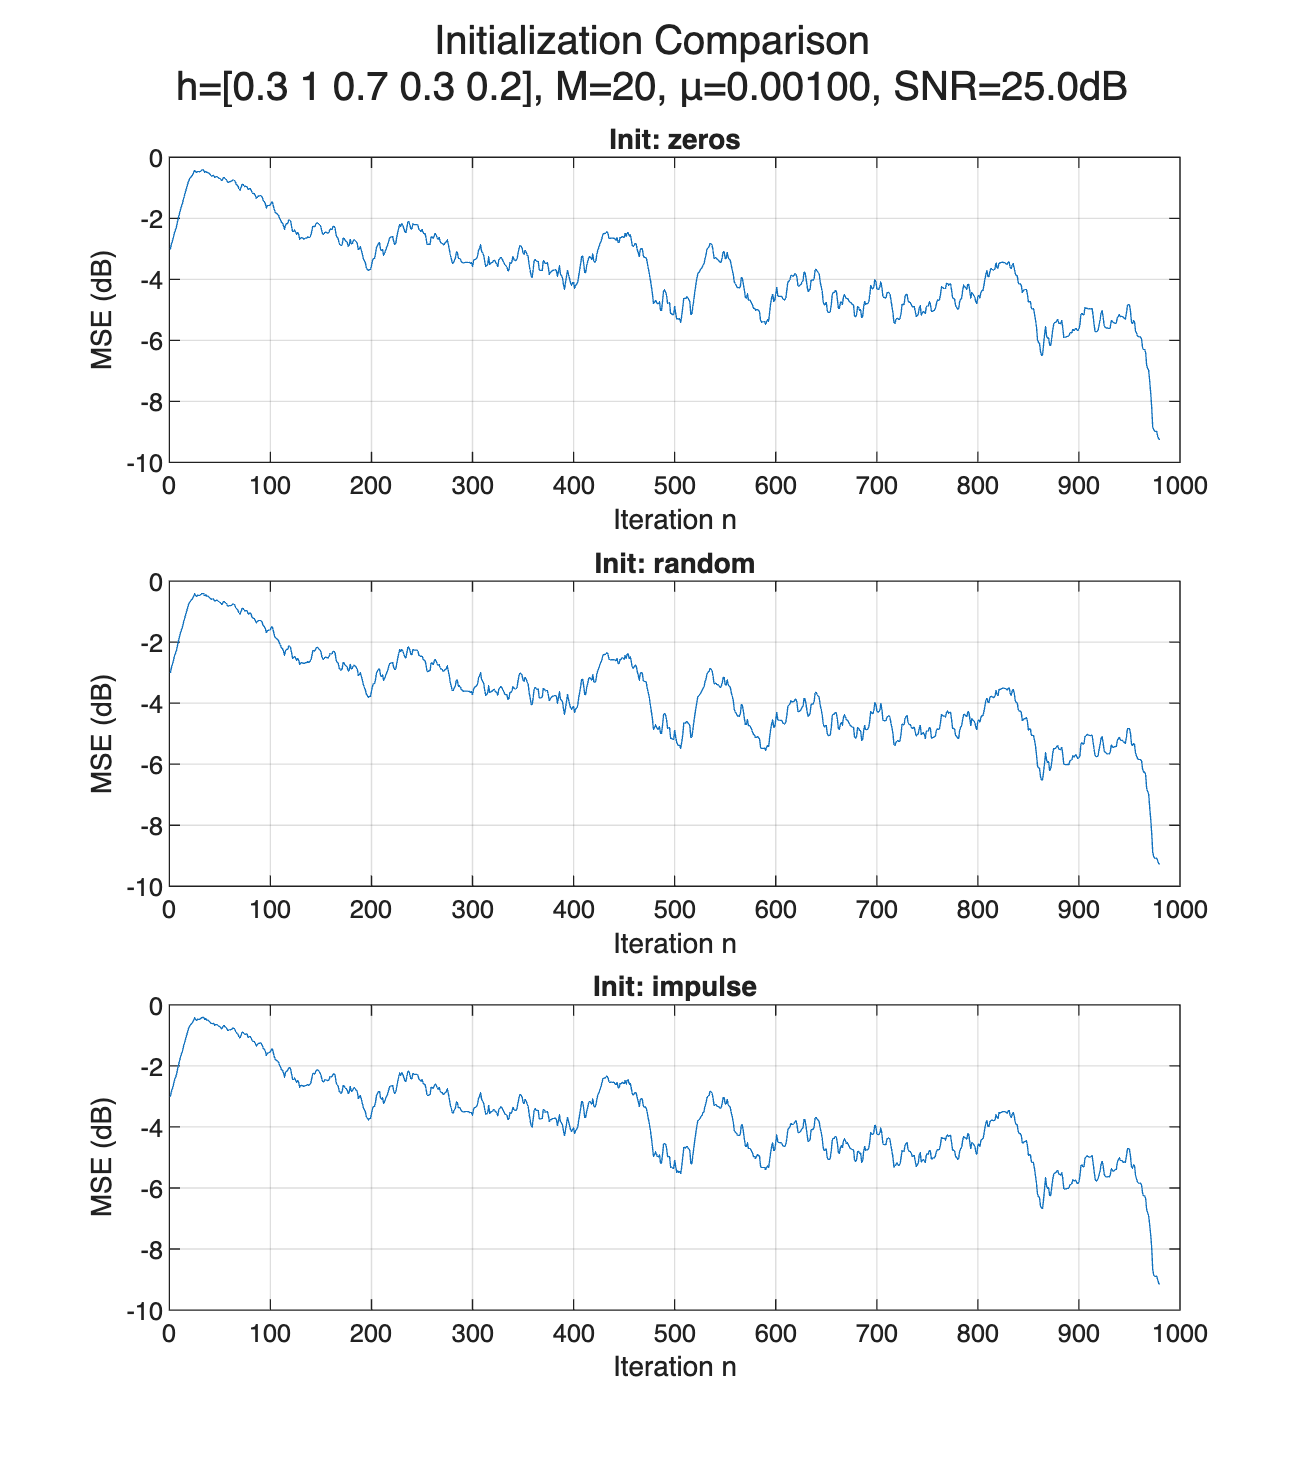


% check initialization comparison
inits = {'zeros', 'random', 'impulse'};

figure('Position', [100, 100, 800, 900])
sgtitle({'Initialization Comparison', ...
         compose("h=%s, M=%d, μ=%.5f, SNR=%.1fdB", mat2str(h), M, mu, snr_db)});

for k = 1:length(inits)
    [gn_init, en_init, ~, ~, ~] = run_equalizer(train, h, mu, M, delay_idx, snr_db, N);
    
    mse_init = conv(en_init(M+1:end).^2, ones(1,window)/window, 'same');
    
    subplot(3,1,k);
    plot(10*log10(mse_init));
    xlabel('Iteration n'); ylabel('MSE (dB)');
    title(sprintf('Init: %s', inits{k}));
    grid on;
end

% TEST 2 (higher snr, longer h, same mu, higher M, more delay)
snr_db = 35;
h = [0.3, 0.5, 1, 0.7, 0.3, 0.2];
mu = 0.001;
M = 29;
delay_idx = 3;

figure; plot_channel(h, snr_db, mu, M);

train_c = V(randi([1,2], 1, 5000));
[gn_c, en_c, ~, ~, noi_power_c] = run_equalizer(train_c, h, mu, M, delay_idx, snr_db, 5000);

figure; plot_equalizer(h, gn_c, en_c, snr_db, mu, M, window);
figure; plot_cascade(h, gn_c, snr_db, mu, M);

[BER_uneq, BER_eq] = compute_bit_error(h, gn_c, M, delay_idx, noi_power_c, V);
fprintf('Test 2 (SNR=%ddB, M=%d, mu=%.4f)\n', snr_db, M, mu);
fprintf('Unequalized BER: %.4f\n', BER_uneq);
fprintf('Equalized   BER: %.4f\n', BER_eq);

% TEST 3 (lower snr, higher mu, same M, same delay)
snr_db = 35;
h = [1, 0.5, 0.3, 0.1]; % MIN PHASE
mu = 0.01;
M = 29;
delay_idx = 1;

figure; plot_channel(h, snr_db, mu, M);

train_c = V(randi([1,2], 1, 5000));
[gn_c, en_c, ~, ~, noi_power_c] = run_equalizer(train_c, h, mu, M, delay_idx, snr_db, 5000);

figure; plot_equalizer(h, gn_c, en_c, snr_db, mu, M, window);
figure; plot_cascade(h, gn_c, snr_db, mu, M);

[BER_uneq, BER_eq] = compute_bit_error(h, gn_c, M, delay_idx, noi_power_c, V);
fprintf('Test 3 (SNR=%ddB, M=%d, mu=%.4f)\n', snr_db, M, mu);
fprintf('Unequalized BER: %.4f\n', BER_uneq);
fprintf('Equalized   BER: %.4f\n', BER_eq);

% TEST 4 (30 snr, shorter h, smaller mu, 30 M, 2 delay)
snr_db = 30;
h = [0.3, 1, 0.7, 0.3, 1];
mu = 0.01;
M = 10;
delay_idx = 2;

figure; plot_channel(h, snr_db, mu, M);

train_c = V(randi([1,2], 1, 5000));
[gn_c, en_c, ~, ~, noi_power_c] = run_equalizer(train_c, h, mu, M, delay_idx, snr_db, 5000);

figure; plot_equalizer(h, gn_c, en_c, snr_db, mu, M, window);
figure; plot_cascade(h, gn_c, snr_db, mu, M);

[BER_uneq, BER_eq] = compute_bit_error(h, gn_c, M, delay_idx, noi_power_c, V);
fprintf('Test 4 (SNR=%ddB, M=%d, mu=%.4f)\n', snr_db, M, mu);
fprintf('Unequalized BER: %.4f\n', BER_uneq);
fprintf('Equalized   BER: %.4f\n', BER_eq);

## finding the best configuration

%% FOR LOOP TESTS
h_tests   = {[1,0.5,0.2], [0.5,1,0.8,0.4,0.1,0.3], [0.5,1,-0.4,0.2], [1,-0.5,0.3, 0.5, 1]};
snr_tests = [20, 25, 30, 35];
M_tests   = [9, 19, 29];
mu_tests  = [0.01, 0.001, 0.0001];

best_per_h = [];  % stores best config for each h
train_c = V(randi([1,2], 1, 5000))

for h_idx = 1:length(h_tests)
    h_cur    = h_tests{h_idx};
    results_h = [];  % results just for this h

    for snr_db = snr_tests
        for M = M_tests
            for mu = mu_tests

                [g_cur, e_cur, ~, ~, noi_power_cur] = run_equalizer(train_c, h_cur, mu, M, delay_idx, snr_db, 5000);
                final_mse = mean(e_cur(end-100:end).^2);
                [BER_uneq, BER_eq] = compute_bit_error(h_cur, g_cur, M, delay_idx, noi_power_cur, V);

                % col: 1=snr, 2=M, 3=mu, 4=MSE, 5=BER_uneq, 6=BER_eq
                results_h = [results_h; snr_db, M, mu, final_mse, BER_uneq, BER_eq];
            end
        end
    end

    % find best config for this h (lowest equalized BER)
    % primary metric: equalized BER
    ber_eq = results_h(:,6);
    min_eq = min(ber_eq);
    
    % find all candidates that achieve the minimum equalized BER
    candidates = results_h(ber_eq == min_eq, :);
    
    % tie-break using unequalized BER (column 5)
    [~, best_local_idx] = min(candidates(:,5));
    
    % final best row
    best_h = candidates(best_local_idx, :);

    fprintf('\n BEST CONFIG FOR h=%s \n', mat2str(h_cur));
    fprintf('SNR = %ddB, M = %d, mu = %.4f\n', best_h(1), best_h(2), best_h(3));
    fprintf('Final MSE: %.6f\n', best_h(4));
    fprintf('Unequalized BER: %.4f\n', best_h(5));
    fprintf('Equalized BER: %.4f\n', best_h(6));

    % plot best config for this h
    plot_channel(h_cur, best_h(1), best_h(3), best_h(2));
    
    train_c = V(randi([1,2], 1, 5000));
    [gn_c, en_c, ~, ~, noi_c] = run_equalizer(train_c, h_cur, best_h(3), best_h(2), delay_idx, best_h(1), 5000);

    plot_equalizer(h_cur, gn_c, en_c, best_h(1), best_h(3), best_h(2), window);
    plot_cascade(h_cur, gn_c, best_h(1), best_h(3), best_h(2));

    % index description: 1=h_idx, 2=snr, 3=M, 4=mu, 5=MSE, 6=BER_uneq, 7=BER_eq
    best_per_h = [best_per_h; h_idx, best_h];
end

%% FIND OVERALL BEST ACROSS ALL H's
[~, overall_best_idx] = min(best_per_h(:,7));
overall_best = best_per_h(overall_best_idx, :);

fprintf('\n OVERALL BEST CONFIGURATION \n');
fprintf('h = %s\n', mat2str(h_tests{overall_best(1)}));
fprintf('SNR=%ddB, M=%d, mu=%.4f\n', overall_best(2), overall_best(3), overall_best(4));
fprintf('Final MSE:       %.6f\n', overall_best(5));
fprintf('Unequalized BER: %.4f\n', overall_best(6));
fprintf('Equalized   BER: %.4f\n', overall_best(7));